## Beamforming

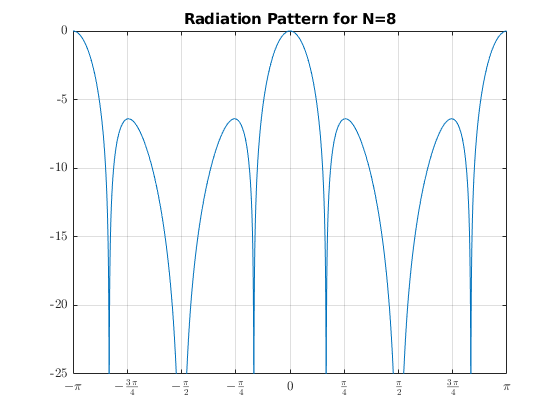

k = 0.001;
N=8;
phi = -pi:k:(pi-k);
lambda = 1;
d = 0.25*lambda;
F = sin(N*((pi*d)/lambda)*sin(phi)) ./ sin(((pi*d)/lambda)*sin(phi));

plot(phi, pow2db(abs(F)/N))
grid on
xlim([-pi pi])
ylim([-25 0])
ticks = [-4*pi -3*pi -2*pi -pi 0 pi 2*pi 3*pi 4*pi] ./ 4;
xticks(ticks)
xlabels = strings(size(ticks));
for i = 1:length(ticks)
    xlabels(1, i) = sprintf("$%s$", latex(simplifyFraction(sym(ticks(i)))));
end
xticklabels(xlabels);
set(groot,'defaultAxesTickLabelInterpreter','latex');
title(sprintf("Radiation Pattern for N=%d", N))